Wallace Gueits                                             PHYS310 EXAM 1

- Why are numerical methods both necessary and useful to science and engineering fields?

Numerical models allow large scale theoretical prototyping  for engineering and investigation for the sciences that

can significantly narrow the scope of the physical work and more expensive tradional methods of investigation to be conducted. We may also find methods and solutions for complex systems with many applications which at the present day have no analytical solutions. 

2. Define a 5x1 matrix named 'a' in MATLAB in which you provide integer-valued entries of your own choosing.

a = [1 2 3 4 5]

a =      1     2     3     4     5


3. Find the maximum value of that matrix.

max(a)

ans =      5

4. Find the sum of the entries.

sum(a)

ans =     15

5. Find the sum of the squared values of the entries.

square = sum(a.^2)

square =     55

6. Plot the elements of 'a' with a red line.

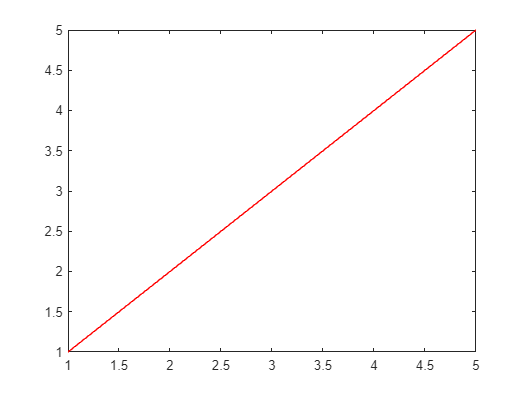

plot(a,'r')

7. Please add a section break here in your live script

%This is another section break

8. Create a program that finds the product of the integers 1 through 100 using a loop.

format long
factr = 1;
for elem = 1:100
    factr = factr * elem;
end
disp(factr)

    9.332621544394410e+157


9. Do the same thing without using a loop, but instead using built in functions.

format long
f = factorial(100)

f =     9.332621544394410e+157

11. Define the function y(x) = tan(x)-1 and determine the positive root nearest zero via false position down to 0.1% relative error.

%false position function called in next section break
function [root, fx, ea, iter] = falsePosition(func, xl, xu, es, maxiter)
% FALSEPOSITION: finds roots of a function using the false-position method
% [root, fx, ea, iter] = falsePosition(func, xl, xu, es, maxiter)
%   INPUTS:
%       func = name of the function to be evaluated
%       xl, xu = lower and upper bounds
%       es = desired relative error (default = 0.0001%)
%       maxiter = maximum number of iterations (default = 200)
%   OUTPUTS:
%       root = estimated root location
%       fx = function value at the estimated root location
%       ea = approximate relative error (%)
%       iter = number of iterations performed

% set default values for es and maxiter if not given
if nargin < 4 || isempty(es)
    es = 0.0001;
end
if nargin < 5 || isempty(maxiter)
    maxiter = 200;
end

% check that the sign of the function changes within the bounds
if func(xl)*func(xu) > 0
    error('Function has the same sign at the upper and lower bounds.')
end

% initialize variables
iter = 0;
xr = xl;
ea = 100;

% loop until desired relative error or maximum number of iterations is reached
while ea > es && iter < maxiter
    % calculate the new estimate using false-position method
    xr_old = xr;
    xr = xu - (func(xu)*(xl-xu))/(func(xl)-func(xu));
    
    % calculate the approximate relative error
    if xr ~= 0
        ea = abs((xr - xr_old)/xr) * 100;
    end
    
    % update the bounds based on the sign of the function at the new estimate
    if func(xr)*func(xl) < 0
        xu = xr;
    elseif func(xr)*func(xu) < 0
        xl = xr;
    else
        ea = 0;
    end
    
    % increment the iteration counter
    iter = iter + 1;
end

% calculate the function value at the estimated root location
fx = func(xr);

% display warning message if maximum number of iterations was reached
if iter == maxiter
    warning('Maximum number of iterations reached.')
end

% display the estimated root location, function value, and approximate relative error
root = xr;
fprintf('Estimated root location: %f\n', root)
fprintf('Function value at root: %f\n', fx)
fprintf('Approximate relative error: %f%%\n', ea)
fprintf('Number of iterations: %d\n', iter)


% Call the falseposition function

func11 = @(x) tan(x) -1;
xl = 0;
xu = 1;
es = .1;
maxit = 50;


[root, fx, ea, iter] = falsePosition(func11, xl, xu, es, maxit);

Estimated root location: 0.785310
Function value at root: -0.000176
Approximate relative error: 0.037584%
Number of iterations: 6



fprintf('Root: %.6f\n', root);

Root: 0.785310


fprintf('Function value at root: %.6f\n', fx);

Function value at root: -0.000176


fprintf('Approximate relative error: %.6f%%\n', ea);

Approximate relative error: 0.037584%


fprintf('Number of iterations: %d\n', iter);

Number of iterations: 6


12. Redo the same problem using the bisection method.


function [root, fx, ea, iter]=bisect(func,xl,xu,es,maxit, varargin)
%bisect: root location zeroes
%   [root, fx, ea, iter] = bisect(func,xl,xu,es,maxit,p1,p2,....):
%   uses bisection method to find the roots of func
% input:
%func = name of function
%   xl,xu = lower and upper guesses
%   es =desired relative error (default = 0.0001%)
%   maxit = maximum allowable interations (default = 50)
%   p1,p2,... = additional parameters used by func
%output:
%   root = real root
%   fx = function value at root
%   ea = approximate relative error (%)
%   iter = number of iterations

if nargin < 3, error('at least 3 input arguments required'), end
test = func(xl, varargin{:})*func(xu, varargin{:});
if test>0, error('no sign change'), end
if nargin<4||isempty(es), es = 0.0001; end
if nargin<5|| isempty(maxit), maxit = 50; end
iter = 0; xr = xl; ea = 100;
while (1)
        xrold = xr;
        xr = (xl + xu)/2;
        iter = iter + 1;
        if xr ~= 0, ea = abs((xr-xrold)/xr)*100;end
        test=func(xl,varargin{:})*func(xr,varargin{:});
        if test < 0
            xu = xr;
        elseif test > 0 
            xl = xr;
        else 
            ea = 0;
        end 
        if ea <= es || iter >= maxit, break, end
end
root = xr; fx = func(xr, varargin{:});

% Call the bisect function

func11 = @(x) tan(x) -1;
xl = 0;
xu = 1;
es = .1;
maxit = 50;


[root, fx, ea, iter] = bisect(func11, xl, xu, es, maxit);

fprintf('Root: %.6f\n', root);

Root: 0.785645


fprintf('Function value at root: %.6f\n', fx);

Function value at root: 0.000493


fprintf('Approximate relative error: %.6f%%\n', ea);

Approximate relative error: 0.062150%


fprintf('Number of iterations: %d\n', iter);

Number of iterations: 11


13. which of the methods converged quicker for the given function and why?

Bisection method: 11 iterations

False position: 6 iterations.

False position is interpolating between two points on the curve, whereas the bisection method is iteratively cutting the range by half each time. Maybe I could make the bisection method faster if I were to start off with a much narrower lower and upper estimate.

14. Solve the same root problem using the newton-raphson algorithm.

function [root, ea, iter]=newtraph(func,dfunc,xr,es,maxit,varargin)
%newstraph: Newton-raphson root location zeroes
% [root,ea,iter] = newtraph(func,dfunc,xr,es,maxit,p1,p2,...):
%input:
%   func = name of function
%   dfunc = name of derivative of function
%   xr = initial guess
%   es =desired relative error (default = 0.0001%)
%   maxit = maximum allowable iterations (default = 50)
%   p1,p2,... = additional parameters used by function
%Output:
%   root = real root
%   ea = approximate relative error (%)
%   iter = number of iterations

if nargin<3,error('at least 3 input arguments required'),end
if nargin<4||isempty(es),es = 0.0001;end
if nargin<5||isempty(maxit),maxit=50;end
iter = 0;
while (1)

    xrold = xr;
    xr = xr -func(xr)/dfunc(xr);
    iter = iter - 1;
    if xr ~= 0, ea = abs((xr -xrold)/xr)*100; end
    if ea <=es || iter >= maxit, break, end
end
root = xr;


%problem 14 newton raphson numerical solution
func11 = @(x) tan(x) -1;
%dfunc = derivative of func
dfunc = @(x) sec(x).^2;
newtraph(func11,dfunc, 1,0.1,50)

ans =    0.785398163457582

15. Solve the same root problem using the seacant method.

%from section 6.4 equations
fun = @(x) tan(x)-1;
x = zeros(0, 1);
x(1) = 1;
delta = 0.01;
iter = 0;

for i = 2:50
    dx = delta * x(i-1);
    x(i) = x(i-1) - (dx * fun(x(i-1))) / (fun(x(i-1) + dx) - fun(x(i-1)));
    iter = iter + 1;
end

root = x(50);
fprintf('positive root nearest zero is: %.5f\n', root);

positive root nearest zero is: 0.78540


16. Solve the same root problem using the built in fzero function.

fun = @(x) tan(x)-1;
i = [0 1];
sol = fzero(fun, i)

sol =    0.785398163397449

17. Describe the difference between a global and local minimum of a function.

For the entire domain of a function, the global minimum is the lowest value of that function. A local minimum takes a certain interval in the total domain of the function and finds the lowest value within it. 

18. Use a golden-section search to find the maximum of the function v(t) = (4*t.^2)*e^(-0.1*t) + 10 in the positive domain of t down to less than 0.001% relative error.

function [x_max, f_max, ea, iter] = goldmax(f, xl, xu, es, maxit, varargin)
% goldmax: maximization golden section search
% [x_max, f_max, ea, iter] = goldmax(f, xl, xu, es, maxit, p1, p2, ...)
% uses golden section search to find the maximum of f
% input:
%   f = name of function
%   xl, xu = lower and upper guesses
%   es = desired relative error (default = 0.0001%)
%   maxit = max allowed iterations (default 50)
%   p1, p2, ... = additional parameters used by f
% output:
%   x_max = location of maximum
%   f_max = maximum function value
%   ea = approximate relative error (%)
%   iter = number of iterations

if nargin < 3, error('at least 3 input arguments required'), end
if nargin < 4 || isempty(es), es = 0.0001; end
if nargin < 5 || isempty(maxit), maxit = 50; end
phi = (1 + sqrt(5)) / 2;
iter = 0;
d = (phi - 1) * (xu - xl);
x1 = xl + d;
x2 = xu - d;
f1 = f(x1, varargin{:});
f2 = f(x2, varargin{:});

while true
    x_int = xu - xl;
    if f1 > f2
        x_opt = x1;
        xl = x2;
        x2 = x1;
        f2 = f1;
        x1 = xl + (phi - 1) * (xu - xl);
        f1 = f(x1, varargin{:});
    else
        x_opt = x2;
        xu = x1;
        x1 = x2;
        f1 = f2;
        x2 = xu - (phi - 1) * (xu - xl);
        f2 = f(x2, varargin{:});
    end

    iter = iter + 1;
    if x_opt ~= 0
        ea = (2 - phi) * abs(x_int / x_opt) * 100;
    end
    if ea <= es || iter >= maxit
        break;
    end
end

x_max = x_opt;
f_max = f(x_opt, varargin{:});

end


fun = @(x) (4*x.^2).*exp(-0.1*x) + 10;
%xl=0 to keep it positive, xu = inf since we can already verify visually
%this function has no global maximum, so any upper limit less than infinity
%will only give the value of the function at that particular point as a
%local max.
goldmax(fun,0,inf,0.001,60)

ans =    NaN

19. define your own 3x2 matrix

b = [1 2; 3 4; 5 6]

b =      1     2
     3     4
     5     6


20. Have MATLAB show the size of the matrix.

sizb = size(b)

sizb =      3     2


21. Change the bottom right entry to a value of 7

b(3,2) = 7;
disp(b)

     1     2
     3     4
     5     7


22. show the transpose of the matrix you defined.

b'

ans =      1     3     5
     2     4     7


23. Use MATLAB to solve for the values of the unknown variables in this set of equations: 2*x + 3*y -3*z = 6,  4*x + y + 2*z = 10, y -2*x -z =0.

%variables. Used matlab symbolic math toolbox package.
syms x y z

func1 = 2*x + 3*y - 3*z == 6;
func2 = 4*x + y + 2*z == 10;
func3 = y - 2*x - z == 0;

soltn = solve([func1, func2, func3], [x, y, z])

soltn = struct with fields:
    x: 3/4
    y: 10/3
    z: 11/6

24. Find the inverse of the coefficient matrix from the above problem.

%just the inverse of the coefficients.

C = [2, 3, -3; 4, 1, 2; -2, 1, -1];
inv(C)

ans =    0.125000000000000                   0  -0.375000000000000
                   0   0.333333333333333   0.666666666666667
  -0.250000000000000   0.333333333333333   0.416666666666667


25. Determine the intersection points of these non-linear equations using fixed point iteration: y = x^2 + x - 10 and y + 3*x*y - x = 0. (two intersection points)

% Define the initial conditions
x_old = -10;
y_old = 10;
tol = 1e-40;
max_iter = 10000;

%functions defnied
f2 = @(y) [(-1 + sqrt(1 - 4*(1)*(y - 10))) / (2*1),(-1 - sqrt(1 - 4*(1)*(y - 10))) / (2*1)];
f1 = @(x) x ./ (1 + 3.*x);

% Start the fixed-point iteration
for i = 1:max_iter
    % Update y
    y_new = f1(x_old);
    
    % Update x for real roots
    x_vals = f2(y_new);
    x_new = x_vals(imag(x_vals) == 0); 
    
    if isempty(x_new)
        % verifies existance of real roots or not, breaks if not
        break;
    elseif length(x_new) > 1
        % just finds me the root closest to x
        [~, idx] = min(abs(x_new - x_old));
        x_new = x_new(idx);
    end
    
    % Check for convergence
    if abs(x_new - x_old) < tol && abs(y_new - y_old) < tol
        break;
    end
    
    % Update x_old and y_old
    x_old = x_new;
    y_old = y_new;
end

% Display the results
disp(['The solution after ' num2str(i) ' iterations is (x,y) = (' num2str(x_new, '%.4f') ', ' num2str(y_new, '%.4f') ').'])

The solution after 8 iterations is (x,y) = (-3.6437, 0.3669).


%It would be cleaner to separate the function above and run it as a
%function call, but its easier to just do it all over again with new
%initial guesses in another quadrant
% Define the initial conditions
x_old = 10;
y_old = 1;
tol = 1e-40;
max_iter = 10000;

% functions defnied
f2 = @(y) [(-1 + sqrt(1 - 4*(1)*(y - 10))) / (2*1),(-1 - sqrt(1 - 4*(1)*(y - 10))) / (2*1)];
f1 = @(x) x ./ (1 + 3.*x);

% Start the fixed-point iteration
for i = 1:max_iter
    % Update y
    y_new = f1(x_old);
    
    % Update x for real roots
    x_vals = f2(y_new);
    x_new = x_vals(imag(x_vals) == 0); 
    
    if isempty(x_new)
        % verifies existance of real roots or not, breaks if not
        break;
    elseif length(x_new) > 1
        % just finds me the root closest to x
        [~, idx] = min(abs(x_new - x_old));
        x_new = x_new(idx);
    end
    
    % Check for convergence
    if abs(x_new - x_old) < tol && abs(y_new - y_old) < tol
        break;
    end
    
    % Update x_old and y_old
    x_old = x_new;
    y_old = y_new;
end

% Display the results
disp(['The solution after ' num2str(i) ' iterations is (x,y) = (' num2str(x_new, '%.4f') ', ' num2str(y_new, '%.4f') ').'])

The solution after 8 iterations is (x,y) = (2.6550, 0.2962).


%there is a third intersection point which can be seen by plugging in
%functions into a graphic calculator. This is the initial method for how I
%solved it with only one root since it was easier and more intuitive to go
%this way as it didn't require a quadratic for function 1 and I could use
%the code from the homework almost exactly as a copy paste.  I think the
%problem only wants the first two solutions from above but I already had
%this done so I might as well include it.
% Define the initial conditions
x_old = 0;
y_old = 0;
tol = 1e-40;
max_iter = 10000;

%function definitions
f1 = @(x) x.^2 + x -10;
f2 = @(y) y ./ (1 - 3.*y);

% Start the fixed-point iteration
for i = 1:max_iter
    % Update y
    y_new = f1(x_old);
    % Update x
    x_new = f2(y_new);
    
    % Check for convergence
    if abs(x_new - x_old) < tol && abs(y_new - y_old) < tol
        break;
    end
    
    % Update x_old and y_old
    x_old = x_new;
    y_old = y_new;
end

% Display the results
disp(['The solution after ' num2str(i) ' iterations is (x,y) = (' num2str(x_new, '%.4f') ', ' num2str(y_new, '%.4f') ').'])

The solution after 7 iterations is (x,y) = (-0.3228, -10.2186).


26. Do problem 25 using the fsolve command built into MATLAB

% Defined sytem in format for fsolve
fun = @(x) [x(2) - x(1)^2 - x(1) + 10;
            x(2) + 3*x(1)*x(2) - x(1)];

% Initial guesses, "guessed" really close to where each is located to not
% have them repeat the same value again
x0_values = [[-3; 2], [0; -10], [2; 0]];  

options = optimoptions('fsolve','Display','none');

%loop search
for i = 1:size(x0_values, 2)
    x0 = x0_values(:, i);
    solution = fsolve(fun, x0, options);
    disp(['The solution for initial guess ' num2str(i) ' is [x, y] = [' num2str(solution(1)) ', ' num2str(solution(2)) '].']);
end

The solution for initial guess 1 is [x, y] = [-3.7582, 0.36578].
The solution for initial guess 2 is [x, y] = [-0.3228, -10.2186].
The solution for initial guess 3 is [x, y] = [2.7477, 0.29727].
